# **CS/SE 4X03 Tutorial Week 6 - Numerical Integration**

## Exercise 1 - 5.1.1

### Recall: Composite Trapezoid Rule


$$\int_a^bf(x)dx \approx T(f;P) = \frac{1}{2}\sum_{i=0}^{n-1}(x_{i+1}-x_i)[f(x_i)+f(x_{i+1})]$$


With uniform spacing, $x_i = a+ih$ and $h=\frac{b-a}{n}$ for $i = 1,2,...,n-1$:


$$\int_a^bf(x)dx \approx T(f;P) = \frac{h}{2}[f(x_0)+f(x_n)] + h\sum_{i=1}^{n-1}f(x_i)$$


### Theorem 1 - Precision of Trapezoid Rule

If $f''$ exists and is continuous on the interval $[a,b]$ and if the composite trapezoid rule $T$ with uniform spacing $h$ is used to estimate the integral $I = \int_a^b f(x)dx$, then for some $\zeta$ in (a,b),


$$I -T = -\frac{b-a}{12}h^2f''(\zeta) = O(h^2)$$


**Question: **Compute an approximate value of:

 
$$\int_{0}^{1}\frac{1}{x^2+1}\text{d}x$$


     by using the composite trapezoid rule with three points. Then compare with the actual value of the integral. Next, determine the error formula and numerically verify an upper bound on it.

**Answer:**

**Given:**

$a = 0$ : Lower bound

$b = 1$ : Upper bound

$n = 3-1=2$ : Number of subintervals

$h = \frac{b-a}{n}=0.5$ : Spacing of subintervals

$x_1 = 0.5$ : Our list of $x_i$, here just the midpoint of $a$ and $b$

$f(x) = \frac{1}{1+x^2}$ : Our function we wish to integrate

$f^{(2)}(x) = \frac{6x^2-2}{(x^2+1)^3}$ : $2^{nd}$ derivative

clear all;
syms x;

f = 1/(1+x^2);
fp = simplify(diff(f,2))

$$fp = \frac{2\,\left(3\,x^{2}-1\right)}{{\left(x^{2}+1\right)}^{3}}$$

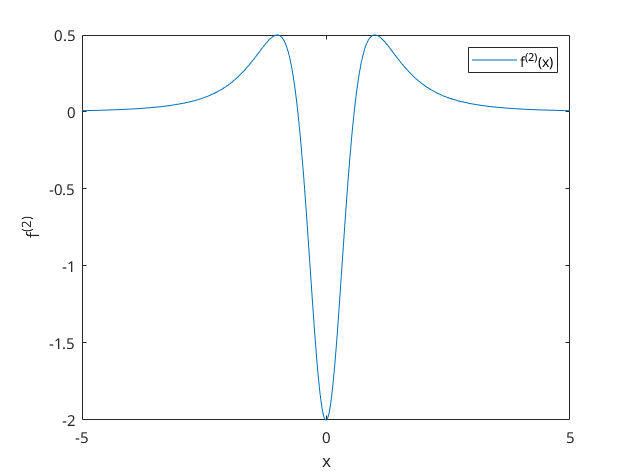

fplot(fp)
legend('f^{(2)}(x)')
xlabel('x')
ylabel('f^{(2)}')

From the above we see that $M=2$


$$M = \max_{x\in [a, b]} \left| f^{(2)}(x)\right| = 2$$



$$f(a) = \frac{1}{1+0^2} = 1$$



$$f(x_i) = \frac{1}{1+0.5^2}=0.8$$



$$f(b) = \frac{1}{1+1^2} = 0.5$$


Now using the composite trapezoid rule:


$$\int_a^b\approx h(0.5f(a)+0.5f(b)+f(x_1))$$



$$= 0.5(0.5(1)+0.5(0.5) + 0.5(0.8)) = 0.775000$$


We can compare this to analytical value: $\arctan(1) = \frac{\pi}{4} \approx 0.785398$


$$\text{error}\approx 0.785398 - 0.775000 = 1.0398\times10^{-2}$$


Using Theorem 1:


$$\text{UBE} = \frac{1}{12}(0.5)^2\times2 = 4.1667\times10^{-2}$$


Where $\text{UBE}$ is the upper bound on the error.

**Note: **Just because Theorem 1 tells us a **bound** for the error, does not mean our error will be that large necessarily.

## **Exercise 2 - 5.1.6**

**Question: **Obtain an upper bound on the absolute error when we compute:

 
$$\int_{0}^{6}\sin^2(x)\text{d}x$$


    by means of the composite trapezoid rule using 101 equally spaced points.	

**Answer:**

**Given:**

$a=0$ : Lower bound

$b=6$ : Upper bound

$n = 101 - 1 = 100$ : Subintervals

$h = \frac{b-a}{n} = 0.06$ : Interval spacing

$f(x) = \sin^2(x)$ : The function

$f^{(2)}(x) = 2\cos(2x)$ : $2^{nd}$ derivative


$$M = \max_{x\in [a, b]} \left| f^{(2)}(x)\right|=2\max_{x\in [0, 6]} \left| \cos(2x)\right| = 2$$


We now use Theorem 1 to obtain a bound on our error:


$$\text{UBE} = \frac{6}{12}(0.06)^2\times2 = 3.6\times10^{-3}$$


## **Exercise 3 - 5.1.7**

**Question: **If the composite trapezoid rule is used to compute $\int_{-1}^{2}\sin(x)\text{d}x$ with $h = 0.01$, give a realistic bound on the error.

**Answer: **

**Given:**

$a=-1$ : Lower bound

$b=2$ : Upper bound

$h = 0.01$ : Interval spacing

$f(x) = \sin(x)$ : The function

$f^{(2)}(x) = -\sin(x)$ : $2^{nd}$ derivative,


$$M = \max_{x\in [a, b]} \left| f^{(2)}(x)\right|=\max_{x\in [-1, 2]} \left| -\sin(x)\right| = 1$$



$$\begin{array}{ll}
\text{UBE} &= \frac{b-a}{12}h^2M\\
&=  \frac{2-(-1)}{12}0.01^2\times1\\
&= 2.5\times10^{-5}
\end{array}$$


## **Exercise 4 - 5.1.8**

**Question: **How large must $n$ be if the composite trapezoid rule is being used to estimate $\int_{0}^{\pi}\sin(x)\text{d}x$ with $\text{error}\leq  10^ {-12}$?

**Answer: **This time we are solving the opposite problem to the previous two exercises.

$a=0$ : Lower bound

$b=\pi$ : Upper bound

$f(x) = \sin(x)$ : The function

$f^{(2)}(x) = -\sin(x)$ : $2^{nd}$ derivative


$$M = \max_{x\in [a, b]} \left| f^{(2)}(x)\right|=\max_{x\in [0, \pi]} \left| -\sin(x)\right| = 1$$



$$\text{UBE} \leq 10^{-12}$$


Now consider that $h=\frac{(b-a)}{n}$ to obtain:


$$\begin{array}{ll}
\text{UBE} &= \frac{b-a}{12}h^2M\\
&= \frac{(b-a)^3}{12n^2}M
\end{array}$$


Finally, we substitute and solve for $n$


$$10^{-12} \geq \frac{(\pi-(0))^3}{12n^2}(1) = \frac{\pi^3}{12n^2}$$



$$\Rightarrow n \geq 1607438$$


## **Exercise 5 - 5.2.19**

**Question: **Show that there exist coefficients $w_0 , w_1 , . . . , w_n$ depending on $x_0 , x_1 , ... , x_n$ and on $[a, b]$ such that:


$$\int_{a}^{b}p(x)\text{d} x =\sum_{i=0}^{n}w_i p(x_i)$$


    for all polynomials $p$ of degree $\leq n$.

**Hint:** Use the Lagrange form of the interpolating polynomial

**Answer: **We define $L_i(x),\; i=0, 1, ..., n$


$$L_i(x)=\prod_{j=0, j\neq i}^{n}\left(\frac{x-x_j}{x_i-x_j}\right), i=0, 1, ..., n.$$


We can represent a polynomial using it's Lagrange interpolation:


$$p(x) = \sum_{i=0}^np(x_i)L_i(x)$$


Integrating,


$$\int_a^bp(x)dx = \int_a^b\sum_{i=0}^n\left(p(x_i)L_i(x)dx\right)$$


But $p(x_i)$ is independent of $x$:


$$=\sum_{i=0}^n\left(p(x_i)\int_a^bL_i(x)dx\right)$$


Thus we see:


$$\int_a^bp(x)dx = \sum_{i=0}^np(x_i)w_i = \sum_{i=0}^np(x_i)\int_a^bL_i(x)dx$$


and so:


$$w_i = \int_a^b L_i(x)dx$$


## **Exercise 6 - 5.2.1**

### Recall: Basic Simpson's Rule


$$\int_a^bf(x)dx \approx S(f;P) = \frac{(b-a)}{6}\left[f(a)+f(b)+4f\left(\frac{a+b}{2}\right)\right]$$


And for the error we have:


$$\text{error} = -\frac{1}{90}\left(\frac{b-a}{2}\right)^5f^{(4)}(\xi),\; \xi\in(a,b)$$


**Question: **Compute $\int_{0}^{1}\frac{1}{x^2+1}\text{d}x$ by the basic Simpson’s Rule, using the three partition points $x = 0, 0.5, 1$. Compare with the true solution.

**Answer:**

$a = 0$ : Lower bound

$b = 1$ : Upper bound

$f(x) = \frac{1}{1+x^2}$ : Our function

$f^{(4)}(x) = \frac{120x^4-240x^2+24}{(x^2+1)^5}$ : $2^{nd}$ derivative


$$M = \max_{x\in [a, b]} \left| f^{(4)}(x)\right|= 24$$



$$f(a) = \frac{1}{1+0^2} = 1$$



$$f\left(\frac{a+b}{2}\right) = \frac{1}{1+0.5^2}=0.8$$



$$f(b) = \frac{1}{1+1^2} = 0.5$$



$$\begin{array}{ll}
\int_a^bf(x)dx &\approx \frac{b-a}{6}\left[f(a)+f(b)+4f\left(\frac{a+b}{2}\right)\right]\\
&= \frac{1}{6}(1+0.8\times4+0.5)\approx0.783333
\end{array}$$


We can compare this to analytical value: $\arctan(1) = \frac{\pi}{4} \approx 0.785398$


$$\text{error} \approx 0.785398 - 0.783333 = 2.065\times10^{-3}$$


**Note: **This is better than the trapezoid rule

Now using the bound for error:


$$\begin{array}{ll}
\text{UBE} &= \frac{1}{2880}(b-a)^5\max_{x\in[a,b]}|f^{(4)}(x)|\\
&= \frac{1}{2880}(1-0)^5\times24\approx 8.333\times10^{-3}
\end{array}$$


This is indeed larger than an our error.

## **Exercise 7 - 5.2.2**

**Question: **Consider the integral $\int_{0}^{2\pi}\sin^2(x)\text{d}x$. Suppose that we wish to integrate numerically, with an error of magnitude less than $10^{-3}$. What width $h$ is needed if we wish to use the following rules?

- Composite Trapezoid Rule

- Composite Simpson's Rule

- Composite Simpson's $\frac{3}{8}$ Rule

**Answer: **This question is mostly just checking the error, and spacing required, for various rules

**Composite Trapezoid Rule:**


$$\text{UBE} = \frac{b-a}{12}h^2M=\frac{2\pi}{12}h^2\times2$$


Now we just solve for $h$ when $UBE \leq 1\times 10^{-3}$


$$\begin{array}{rl}
\text{UBE} &=\frac{\pi}{3}h^2\leq0.003\\
\Rightarrow h &\geq \sqrt{\frac{0.003}{\pi}} \approx 0.0309
\end{array}$$


**Composite Simpson's Rule:**

First we need the maximum of the fourth derivative:


$$\begin{array}{rl}
f^{(4)}(x) &= -8\cos(2x)\\
\Rightarrow \max_{x\in[a,b]}\left|f^{(4)}(x)\right| &= 8
\end{array}$$


Now solve for $h$


$$\begin{array}{rl}
\text{UBE} &= \frac{1}{180}(b-a)h^4\max_{x\in[a,b]}\left|f^{(4)}(x)\right| = \frac{4\pi}{45}h^4\\
\Rightarrow h &\geq \sqrt[4]{\frac{0.045}{4\pi}}\approx 0.2446
\end{array}$$


**Composite Simpson's **$\mathbf\frac{3}{8}$ **Rule**


$$\text{UBE} = \frac{1}{80}(b-a)h^4\max_{x\in[a,b]}\left|f^{(4)}(x)\right| = \frac{\pi}{5}h^4$$


Once again, we solve for $h$:


$$\begin{array}{rl}
\frac{\pi}{5}h^4 &\leq 0.001\\
\Rightarrow h &\geq \sqrt[4]{\frac{0.005}{4\pi}}\approx 0.1412
\end{array}$$


## **Exercise 8 - 5.2.4**

**Question: **Find an approximate value of $\int_{1}^{2}x^{-1}\text{d}x$ using composite Simpson’s Rule with $h = 0.25$. Give a bound on the error.

**Answer:**

$a=1$ : Lower bound

$b=2$ : Upper bound

$h = 0.25$ : Subinterval spacing

$f(x) = \frac{1}{x}$ : The function

$f^{(4)}(x) = \frac{24}{x^5}$ : $4^{th}$ derivative


$$M = \max_{x\in [a, b]} \left| f^{(2)}(x)\right|=\max_{x\in [1, 2]} \left| \frac{24}{x^5}\right| = 24$$


Plugging all this into our error bound for Simpson's Rule gives us our answer:


$$\begin{array}{ll}
\text{UBE} &= \frac{b-a}{180}h^4\max_{x\in[a,b]}|f^{(4)}(x)|\\
 &= \frac{1}{180}\times0.25^4\times24 \\
&\approx 7.74\times10^{-4}
\end{array}$$
